clc;clear;
a = 8.8; 
b = 0.087580;
theta = readmatrix('theta1.xlsx');
x=readmatrix('x1.xlsx');
y=readmatrix('y1.xlsx');
l=readmatrix('l1.xlsx');
k_0=[];

%判断
found = false;
for i = 1:420
    for k = 1:223

            %AC的长度
            d_1 = 0.313249 + 0.15;
            theta_b = (theta(k,i) + theta(k+1,i))/2;
            
            %A的坐标
            r_a = a-b*theta(1,i);
            x_a = r_a*cos(theta(1,i));
            y_a = r_a*sin(theta(1,i));

            %B的坐标和半径
            x_b = (a-b*theta_b)*cos(theta_b);
            y_b = (a-b*theta_b)*sin(theta_b);
            r_b = a-b*theta_b;

            %AB的距离
            d_2 = sqrt((x_a - x_b)^2 + (y_a - y_b)^2); 
            
            % 极限距离
            if d_2 < d_1
                disp('找到所求的时刻了');
                k_0 = [k_0, k];
                found = true;  % 设置标志变量为真
                break;  % 退出内层循环
            else
                disp('继续');

        end
    end
    
    if found  % 检查标志变量
        break;  % 退出外层循环
    end
end

继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继续
继

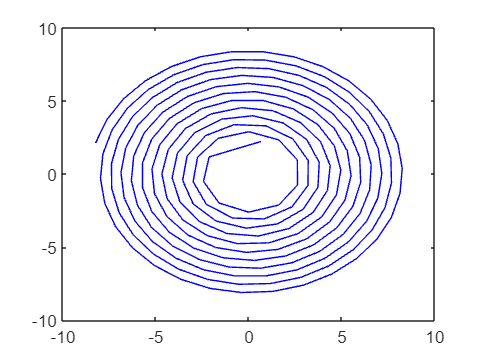


if found
    disp(['符合条件的 i 值为: ', num2str(i)]);
end
figure()
p1_x = x(:,412);
p1_y = y(:,412);
plot(p1_x,p1_y,'b');